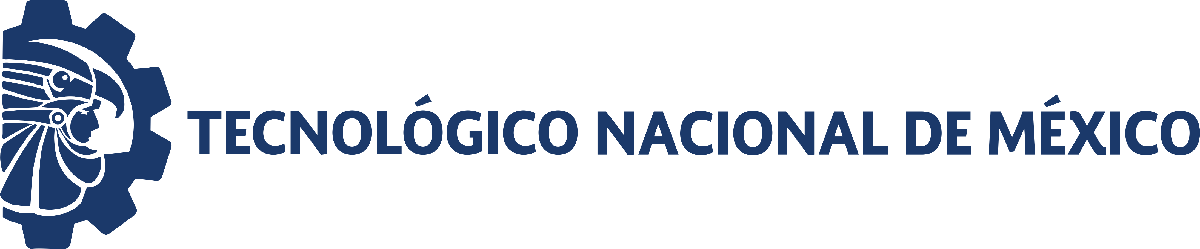                                 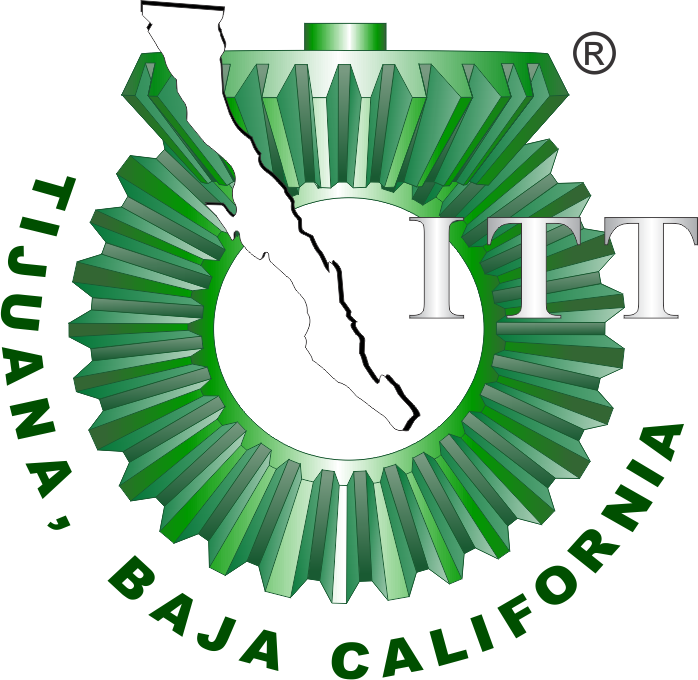

# Práctica tres: Sistema musculoesquelético

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

                                                                            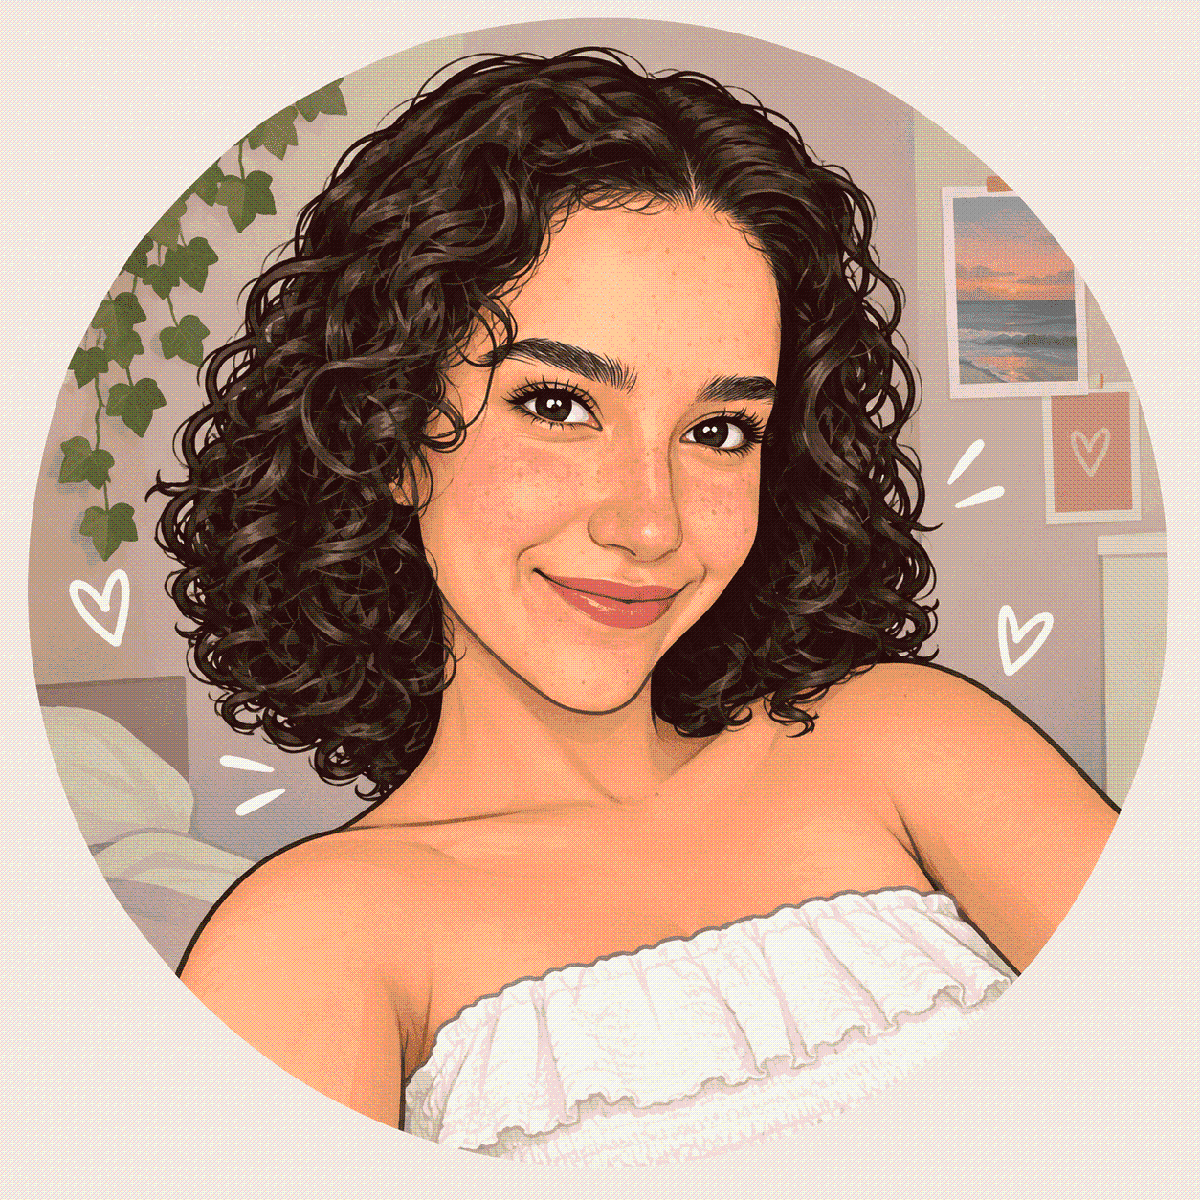

Nombre del alumno: Sara Gutiérrez Hernandez

Número de control: 23212734

Correo institucional: L23212734**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('sistema4')
parameters.StopTime = '10';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-3';
parameters.TimeSaveName = 't';
x = sim('sistema4',parameters);

## Respuesta: Control y caso

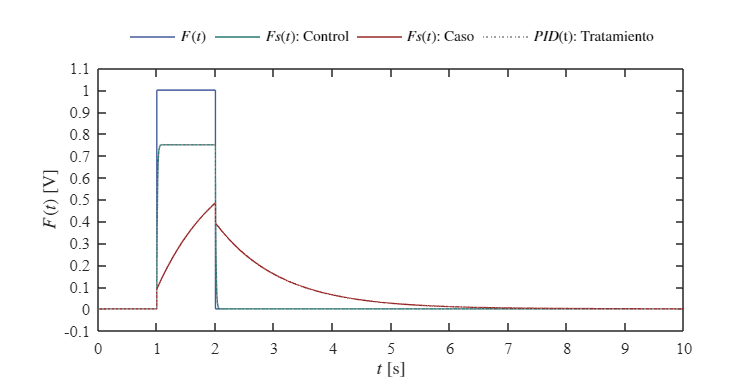

plotsignals(x.t,x.F,x.Fsx,x.Fsy,x.PID,'Control y caso')

## Función: Respuesta de la simulación

function plotsignals(t,s,s1,s2,s3,caso)
    set (figure(),'color','w')
    set (gcf,'units','inches','position',[1,1,7,3.5])
    set (gca,'fontname','times new roman','fontsize',11)
    hold on; grid off; box on;
    
    clr1 = [66, 91, 154]/255;
    clr2 = [40, 122, 116]/255;
    clr3 = [151, 40, 40]/255;
    clr4 = [0.5, 0.5, 0.5];

    if caso == "Control y caso"
        plot (t,s,'-','LineWidth',0.25,'Color',clr1)
        plot (t,s1,'-','LineWidth',0.25,'Color',clr2)
        plot (t,s2,'-','LineWidth',0.25,'Color',clr3)
        plot (t,s3,':','LineWidth',0.25,'Color',clr4)
     
        L = legend('$F(t)$','$Fs(t)$: Control','$Fs(t)$: Caso','$PID$(t): Tratamiento');
    end

    set(L,'interpreter','latex','location','northoutside','orientation','horizontal','box','off')    
    xlabel('$t$ [s]','interpreter','latex')
    ylabel('$F(t)$ [V]','interpreter','latex')

    xlim([0 10]); xticks(0:1:15)
    ylim([-0.1 1.1]); yticks(-0.1:0.1:1.1)

    exportgraphics(gcf,[caso,'.matlab.pdf'],'contenttype','vector')
end